close all;
clear all;

t = readtable('data/eoarchean_geochemistry.xlsx');

t.Properties.VariableNames = lower(t.Properties.VariableNames);


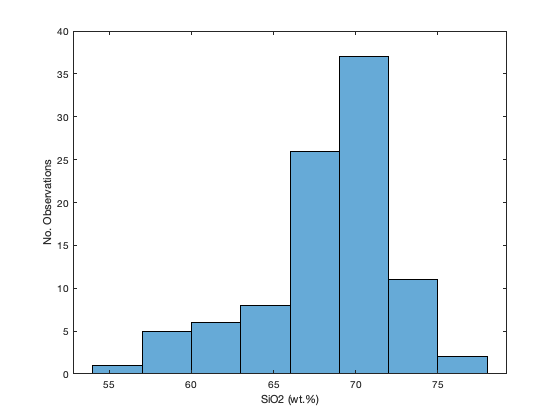

figure;
histogram(t.sio2);
xlabel('SiO2 (wt.%)');
ylabel('No. Observations');

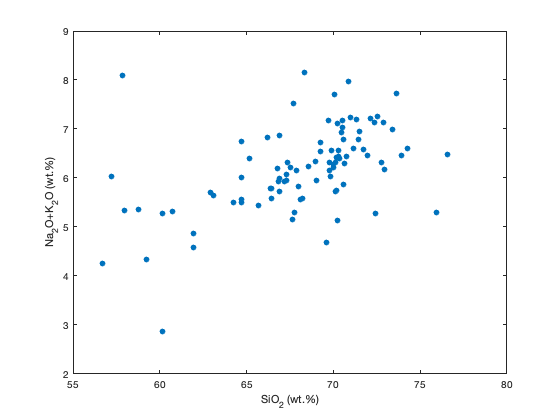


figure;
scatter(t.sio2,t.k2o+t.na2o,'filled');
xlabel('SiO_2 (wt.%)');
ylabel('Na_2O+K_{2}O (wt.%)');
set(gca,'Box','on');

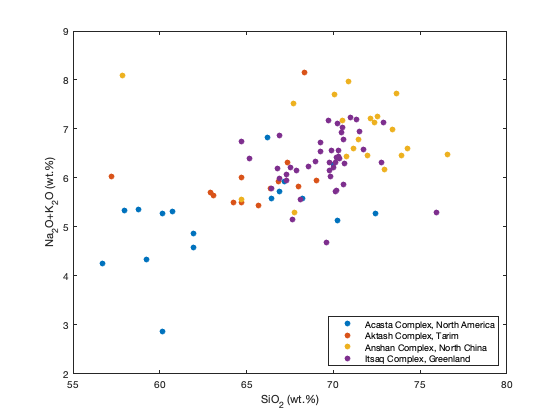

figure;

region = unique(t.region);
for i = 1:length(region)
    ind = strcmp(region{i},t.region);
    scatter(t.sio2(ind),t.k2o(ind)+t.na2o(ind),'filled');
    hold on;
end
xlabel('SiO_2 (wt.%)');
ylabel('Na_2O+K_{2}O (wt.%)');
set(gca,'Box','on');
legend(region,'Location','southeast');